## TOPIC 12: Function handles and recursion

ENGR105, 10/13/20

#### Reminder: function handles 

Functions can be passed as variables and referenced/invoked by using this new variable. A variable that has been assigned to a function is referred to as a function handle. Function handles may be created with **user-defined** or **built-in** functions.

% Create function handle with product function
a = @prod;
a([3,2,1,2])

ans = 12

b = @mod;
% Create function handle with modulus function
b(3,2)

ans = 1

Function handles are **useful** because these enable us to** pass one function into another function**. Consider the following function.

% Create a function handle
f1 = @sum;
% Define a vector
c = 1:4

c =      1     2     3     4


% Call function that takes the handle and vector as inputs
fxn1(f1,c)

The output of this function is...10


Where else have we seen function handles? **We saw them when solving systems of nonlinear equations (****Topic 3 / Lecture 4****).**

Here, `eqnSet` contained a set of nonlinear equations to be solved:

How does `fsolve` take in a function handle to solve the set of equations? Let's consider a more familiar example.

#### Practice problem: a root-finding numerical solver

**Create a function** that uses the Newton-Raphson method to find the root of any arbitrary (well-behaved) input function. **Apply this function** to find the root of the following equation, where $g\left(t\right)$ could represent a *temporal concentration profile*, signal, or other *time-dependent function*.

        
$$g\left(t\right)=t+e^{-t} -4$$


**Checking in**: what does it mean to find the *root of an equation*? It means solving for when that function is **equal to zero**.               

% Time vector

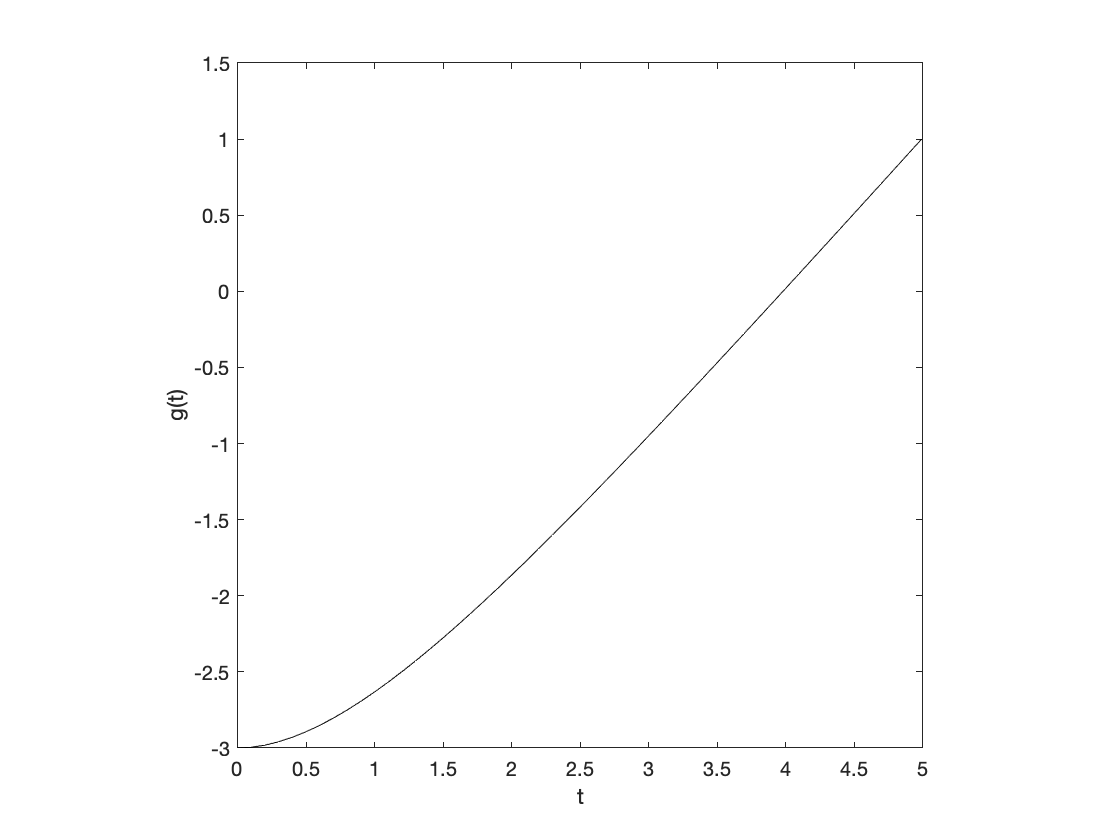

t = 0:0.1:5;       % Time vector
g = t + exp(-t)-4; % Function g(t)
plot(t,g,'k-')
axis square
xlabel('t')
ylabel('g(t)')

Start by remembering our systematic approach.

**PRO:**

- **P**lan, **P**repare, and **P**seudocode

- w**R**ite **R**ough (increments of code) and **R**efine 

- **O**ptimize and improve

**Step 1: Plan, prepare, pseudocode**

Recall from earlier, the Newton-Raphson method is an iterative algorithm for finding a root (based on an initial guess) of any well-behaved function. The Newton-Raphson equation is given by the following:

                
$$x_{n+1} =x_n -\frac{f\left(x_n \right)}{f^{\prime } \left(x_n \right)}$$


In **Topic 7 / Lecture 8**, we found the root of the following $f\left(x\right)$ by creating a script that applies the Newton-Raphson method.

            
$$\begin{array}{l}
f\left(x\right)=x^4 +2{\left(x-2\right)}^2 -20\\
f^{\prime } \left(x\right)={4x}^3 +4\left(x-2\right)
\end{array}$$


% Script for using the Newton-Raphson method to solve for f(x)

% Step 1: specify initial guess
xn = 5; % initial guess
xprev = inf; % Variable to store previous xn value -> ensure it is 
           % not xn to enter while loop

% Step 2: iterate until xn -> xn+1
while abs(xn - xprev) > 10^-5
    
    % Step 3: evaluate function at xn
    fn = xn^4 + 2*(xn-2)^2 - 20;
    % Step 3a: evaluate derivative at xn
    f_prime_n = 4*xn^3 + 4*(xn-2);
    
    % Instead of calculating the "next" x value, store the previous xn
    % value
    xprev = xn;
    
    % Step 3b: update xn to next value for the iteration
    xn = xn - fn/f_prime_n;
end
disp(xn)

    2.1141



**Step 2****: **w**R**ite **R**ough (increments of code) and **R**efine (to code a new application)

%Determine root of original f(x)
rootF = newtonSolve(@originalEqn, 5, 10^-5)

    2.1141



rootF = 2.1141

**Apply this function to the problem here:**

rootG = newtonSolve(@originalEqn, 5, 10^5)

    2.1141



rootG = 2.1141

newEqn(rootG)

ans =    -1.7652    0.8793


**We have thus created our first function that works as a numerical solver!**

#### Anonymous functions

Function handles can also be used to store **anonymous functions**. Anonymous functions are **not "only" the built-in function **or** a custom function stored in a **`.m`** file**, but are associated with a variable. These are useful for smaller/repeatable computations that don't demand a full function and accessibility from multiple functions. Anonymous functions may take in one to multiple inputs, can only return one output, and begin with a list of input variables `@(var1,var2,…,``varN``).`

- Example operating on a **scalar**:

% Anonymous function of a single input operating on a
% scalar.
myFunc = @(x) x^2 + 2*x + 1;
res1 = myFunc(1)

res1 = 4

- Example on a **vector**:

% Anonymous function of a single input operating on a
% vector.
myFunc = @(x) x.^2 + 2.*x + 1;
res2 = myFunc([1:4])

res2 =      4     9    16    25


- Example with **multiple inputs**:

% Anonymous function of a multiple inputs operating on
% scalars.
%x and y are the inputs
myFunc = @(x,y) x^2 + 2*y +1;
res3 = myFunc(1,3)

res3 = 8


 % Anonymous function of a multiple inputs operating on
% vectors.
myFunc = @(x,y) x.^2 + 2.*y +1;
res4 = myFunc([1,2,2,1],4:7);



- Example using** built-in function**

mod2 = @(x) mod(x,2);
mod2(3)

ans = 1

**Note**: this is different from a "simple" function handle based only on a built-in function. Here, we define a function handle that only takes *one* input. Previously, the function handle must take *two* inputs.

**Example**. Plot the following equation, $f\left(x\right)$, over the domain $x\in \left\lbrack 0,10\right\rbrack$ for $a=0\ldotp 5,\;1,\;\textrm{and}\;5\;$.

            
$$f\left(x\right)=e^{-a\;x}$$


% Plot x vector
x = 0:0.1:10;
% Define function handle
f = @(a) exp(-a*x)

f = function_handle with value:
    @(a)exp(-a*x)


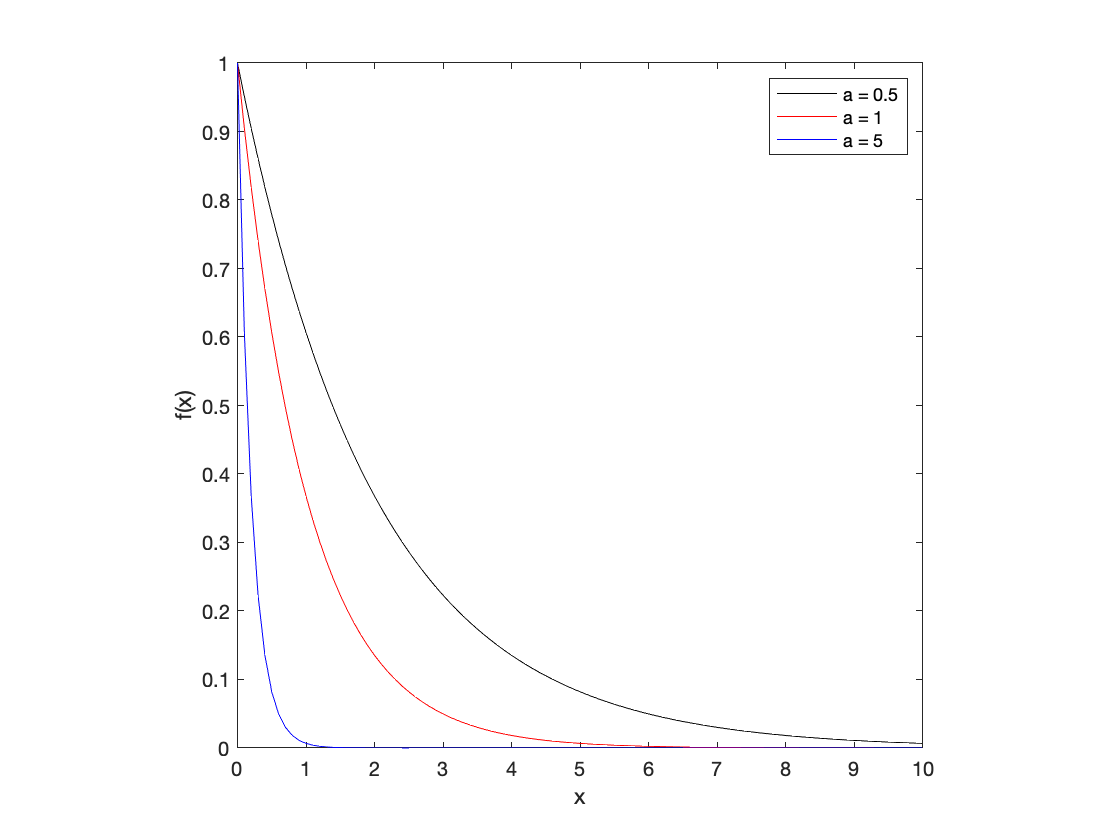


% Plot function for each a
plot(x,f(0.5),'k-')
hold on     % plot on the same set of axis
plot(x,f(1),'r-')
hold on     % plot on the same set of axis
plot(x,f(5),'b-')
hold off    % turn "off" plotting on the same set of axis

axis square
legend('a = 0.5','a = 1', 'a = 5')
xlabel('x')
ylabel('f(x)')

**Note**: anonymous functions (and function handles) can help reduce the frequency of recurring errors.

### Recursion

To *repeat tasks* in a computational environment, one could either use loops (as we have seen before) or call a **recursive function**. Recursive functions call themselves. When a function calls itself, it "opens" a new implementation of the function that is distinct from the original invocation. Consider the function `recursiveAdd`, defined at the end of this LiveScript document.

The following schematic indicates what will happen when this is called:

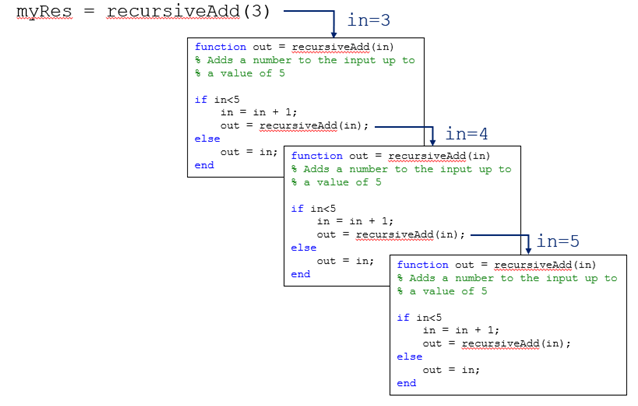

**Once the logical statement is not satistifed**, each invocation of the function will output the same entity.

% Call the recursive function
x = recursiveAdd(3)

x = 5

#### Example: Revisiting the fibonacci sequence

Earlier in this course, we created code to calculate either the first `n` entries of the Fibonacci sequence or all elements less than some integer. For example, consider the latter, in which we can use a `while` loop to calculate all elements of the Fibonacci sequence less than 50.

% Max value of entries in Fibonacci sequence
n = 50;
% Define first two entries
x(1) = 0;
x(2) = 1;
% Iterate as long as the last element is less than 100.
while x(end) < n
    % If the last element is less that 100, add the next element of the
    % Fibonacci sequence to the vector
	x(end+1)=x(end)+x(end-1);
end
x(end)=[];  % Remove last element
disp(x)

     0     1     1     2     3     5     8    13    21    34



The same process can be accomplished using **recursion**. Consider the following function.

% Calculate Fibonacci sequence vector containing elements less than 50
x = recursiveFib(0:1,50)

x =      0     1     1     2     3     5     8    13    21    34


**Recursion can be useful:**

- **Not all languages support loops** (e.g. Haskell)

- Loops may, in some cases, require more complex code/indexing that leads to a* higher probability of errors.*

Recursion can have **limitations**:

- First, recursive solutions may involve extensive overhead because they use function calls.

- Each time you make a call you use up some of your memory allocation. If the recursion is deep – that is, if there is a large number of recursive calls – then you may run out of memory.

#### Example: calculate the factorial of a number

Consider calculating the factorial of a number:

        
$$\textrm{fact}\left(n\right)=\left\lbrace \begin{array}{ll}
1 & n=0\\
n\cdot \textrm{fact}\left(n-1\right) & n>0
\end{array}\right.$$


We can solve this problem using either recursion or loops in MATLAB. Consider the following recursive function.

The factorial of a number may be calculated by calling this **recursive function**. However, "out-of-memory" errors will arise for **large input numbers**.

n = 50000;
% Call recursive function
x = fact(n);

This issue is avoided by using a simple `for` loop.

fact_n = 1;
for m = 1:n
    fact_n = fact_n*m;
end

**Takeaway**: recursion is another tool that, in the right context, will yield simple, easy-to-troubleshoot code.

**Functions stored at the end of the document.**

function fxn1(f,x)
    % Example function
    output = f(x);
    disp(strcat('The output of this function is... ',num2str(output)));
end

**Functions for practice problem: Newton-Raphson example**

% Script for using the Newton-Raphson method to solve for f(x)
function xn = newtonSolve(F, xn, tol)
% Step 1: specify initial guess
    xn = 5; % initial guess
    xprev = inf; % Variable to store previous xn value -> ensure it is 
               % not xn to enter while loop

    % Step 2: iterate until xn -> xn+1
    while abs(xn - xprev) > 10^-5

        % Step 3: evaluate function at xn
        f = F(xn); 
        % Step 3a: evaluate derivative at xn
        f_prime_n = 4*xn^3 + 4*(xn-2);

        % Instead of calculating the "next" x value, store the previous xn
        % value
        xprev = xn;

        % Step 3b: update xn to next value for the iteration
        xn = xn - f(1)/f(2);
    end
    disp(xn)
    
end

function F = originalEqn(x)
    %function
    F(1) = x^4 + 2*(x-2)^2 - 20;
    %derivative of function 
    F(2) = 4*x^3 + 4*(x-2);
end


function G = newEqn(x)
    % Function of interest
    G(1) = x + exp(-x) - 4;
    % Derivative of function of interest
    G(2) = 1 - exp(-x);
end


**Function examples for recursion**

function out = recursiveAdd(in)
    % Adds a number to the input up to
    % a value of 5
     
    if in<5
        in = in + 1;
        out = recursiveAdd(in);
    else
        out = in;
    end
end

function x = recursiveFib(x,maxVal)
    % Function using recursion to create a Fibonacci sequence vector

    % If the last element is less that maxVal, add the next element of the
    % Fibonacci sequence to the vector
    if  x(end-1) + x(end) < maxVal
        % Calculate next entry
        x(end+1) = x(end)+x(end-1);
        % Use recursion to repeat the process
        x = recursiveFib(x,maxVal);
    end
end

function y = fact(n)
    % Recursive function for determining the factorial
    
    % Specify the number we are interested in solving the factorial for
    y = n;
    
    % Specify the "lower limit" in the factorial calculation
    if n == 0
        y = 1;
    else
        % We multiply by all the integers before the input,
        % one at a time...
        y = y*fact(n-1);
    end 
end